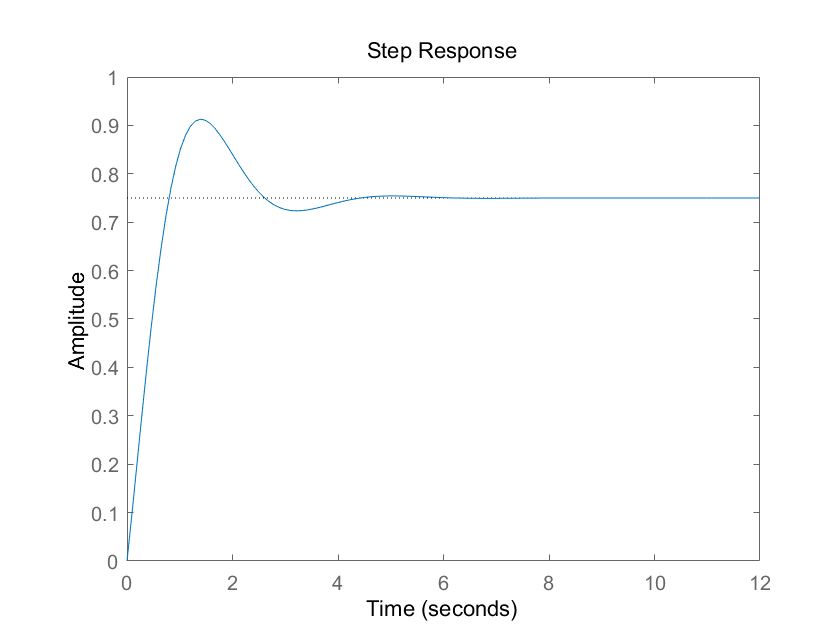

clear
clc

num = [1 3];
den = [1 2 4];
step(num,den,12);

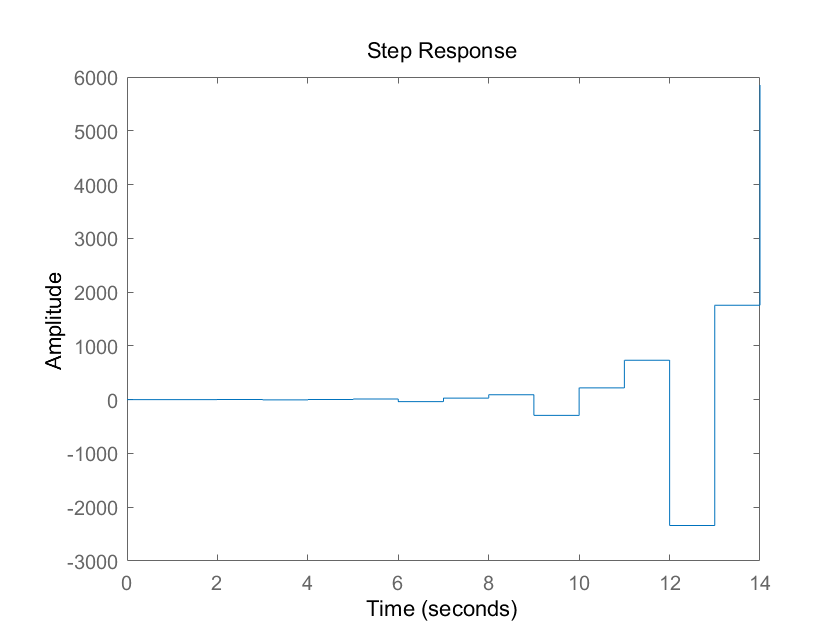


dstep(num,den,15)

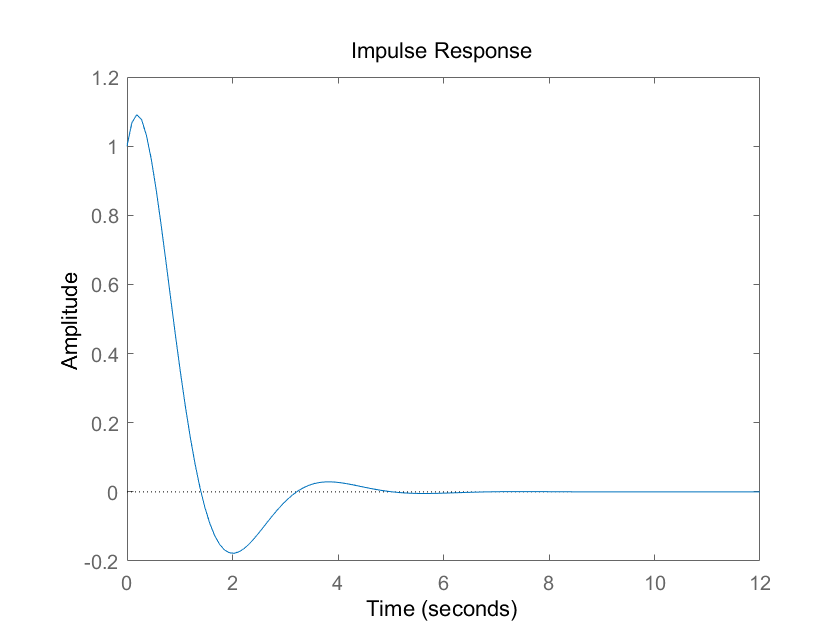


impulse(num,den,12)

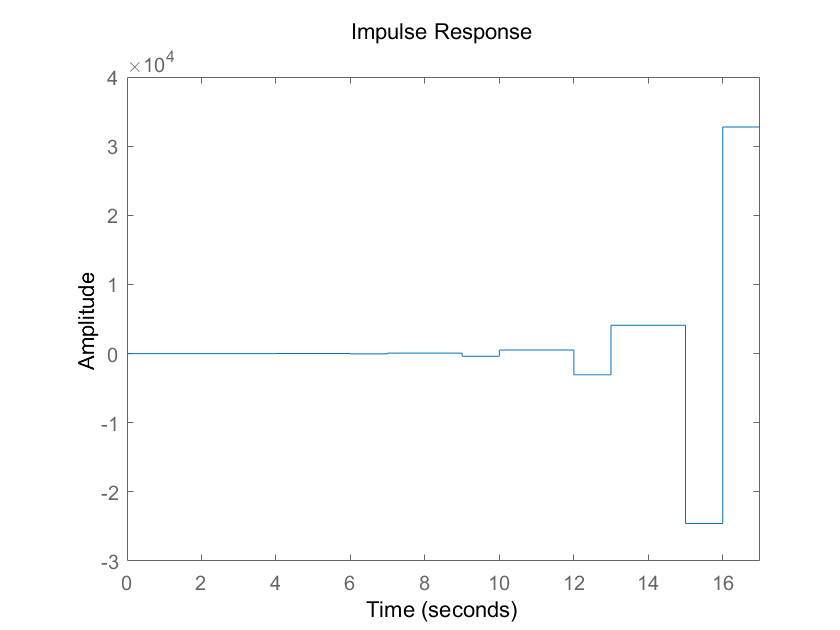


dimpulse(num,den,18)


% initial

% dinitial

sys = tf(num,den)

sys =
 
      s + 3
  -------------
  s^2 + 2 s + 4
 
Continuous-time transfer function.



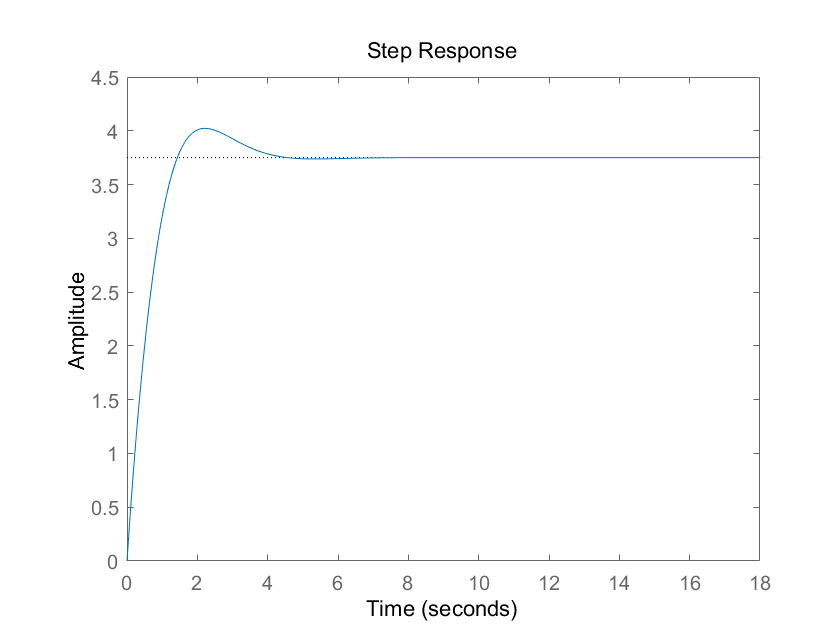

% lsim

% dlsim

num = [5 25 30];
den = [1 6 10 8];
step(num,den,18)

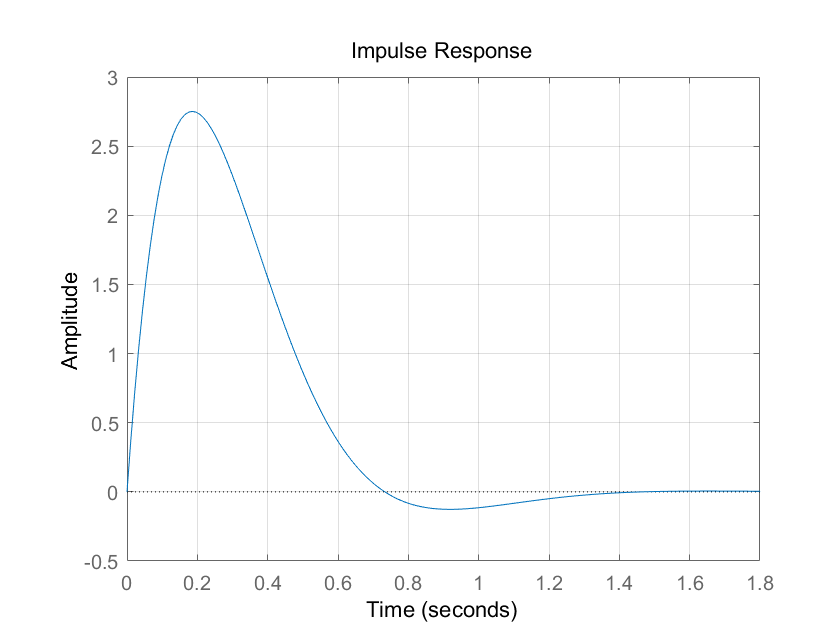



impulse([36],[1,8.4,36]),grid on

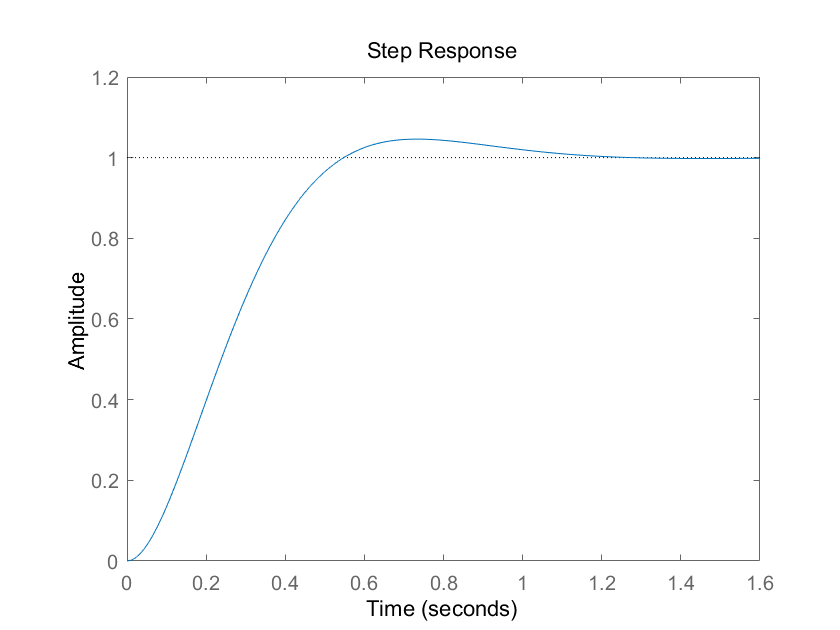

step([36],[1,8.4,36])


sys = tf([36],[1,8.4,36])

sys =
 
         36
  ----------------
  s^2 + 8.4 s + 36
 
Continuous-time transfer function.



[a,b,c,d]=tf2ss([36],[1,8.4,36])

a =    -8.4000  -36.0000
    1.0000         0


b =      1
     0


c =      0    36


d = 0

% initial(a,b,c,d)

clear
clc
clf

Wn = 6

Wn = 6

kesai = [0.1:0.1:1,2]

kesai =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    2.0000


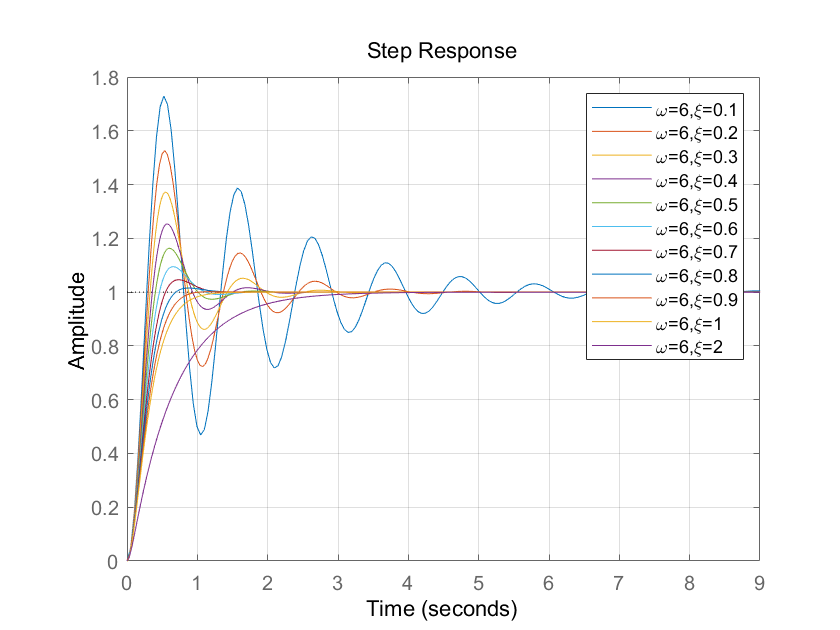

le = [];
x = '\omega=6,\xi=';
hold on
for kos=kesai
    num = Wn^2;
    den = [1,2*kos*Wn,Wn^2];
    step(num,den);
    
    num2str(kos);
    y = [x,num2str(kos)];
    le = [le,string(y)];
    
end
legend(le)
grid on
hold off

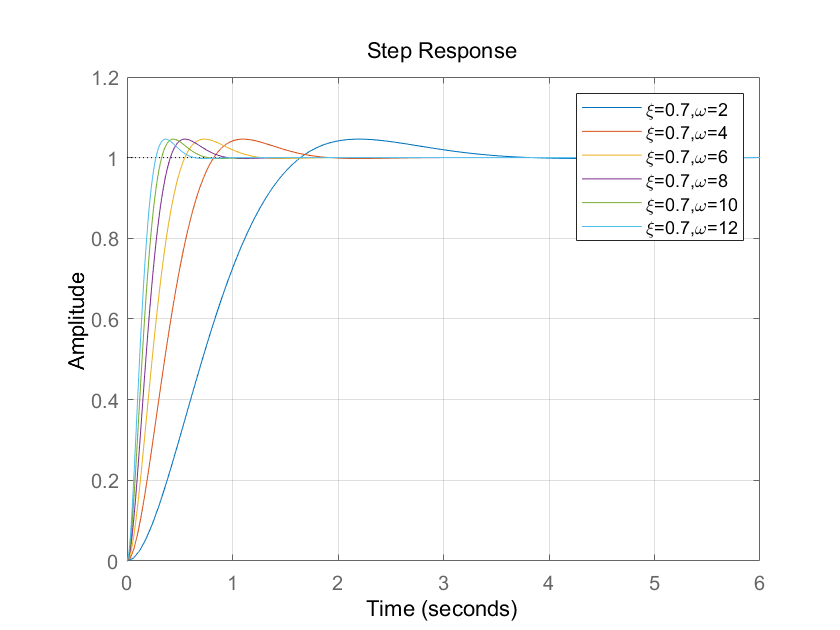

clear
clc
clf

le = [];
x = '\xi=0.7,\omega=';
w = [2:2:12];
kesai = 0.7;
hold on
for Wn = w
    num = Wn^2;
    den = [1,2*kesai*Wn,Wn^2];
    step(num,den,6)
    
    num2str(Wn);
    y = [x,num2str(Wn)];
    le = [le,string(y)];
    
end
legend(le)
grid on
hold off

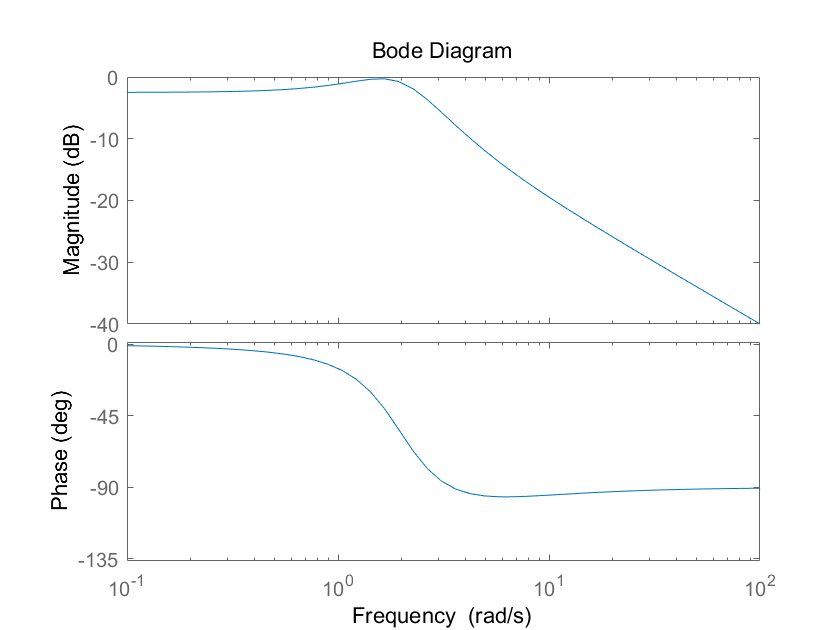

clear
clc

num = [1,3];
den = [1,2,4];
bode(num,den)

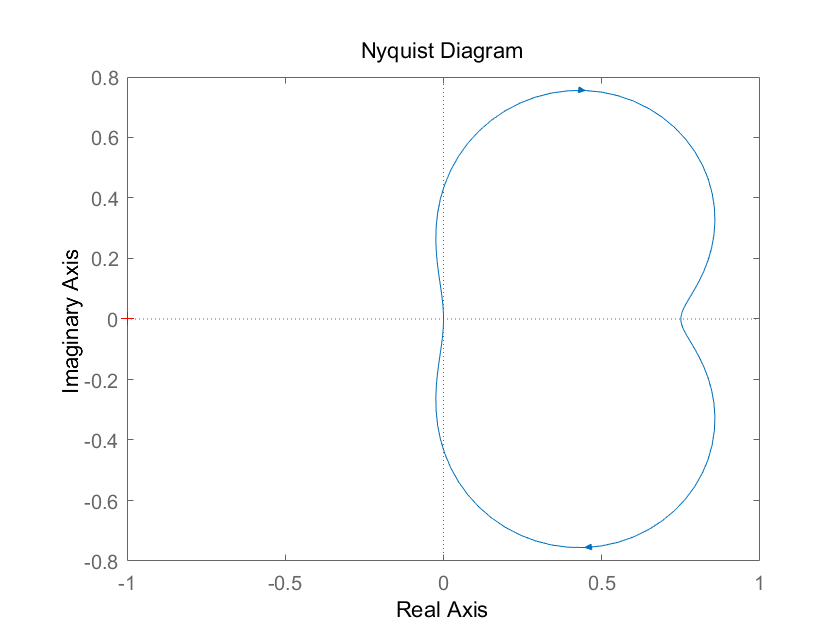


nyquist(num,den)

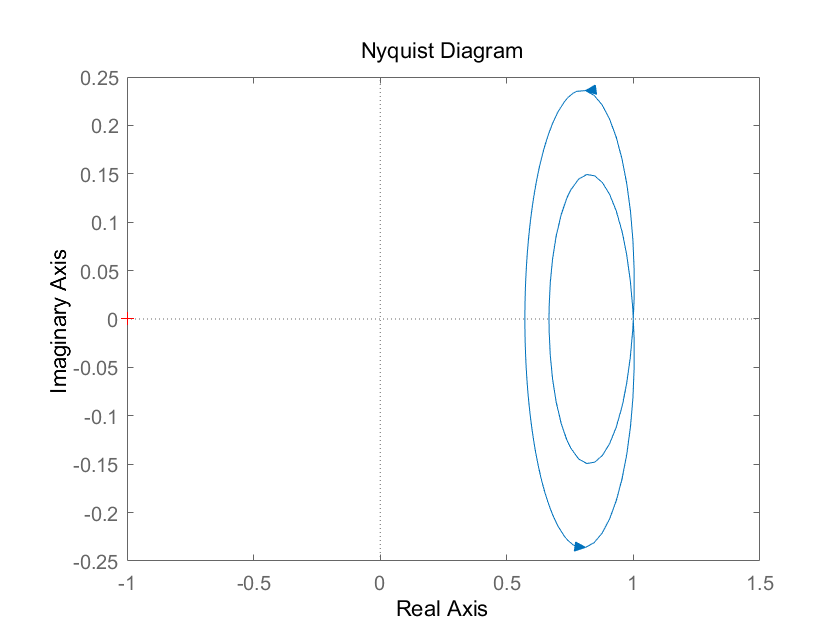


dnyquist(num,den,0.01)

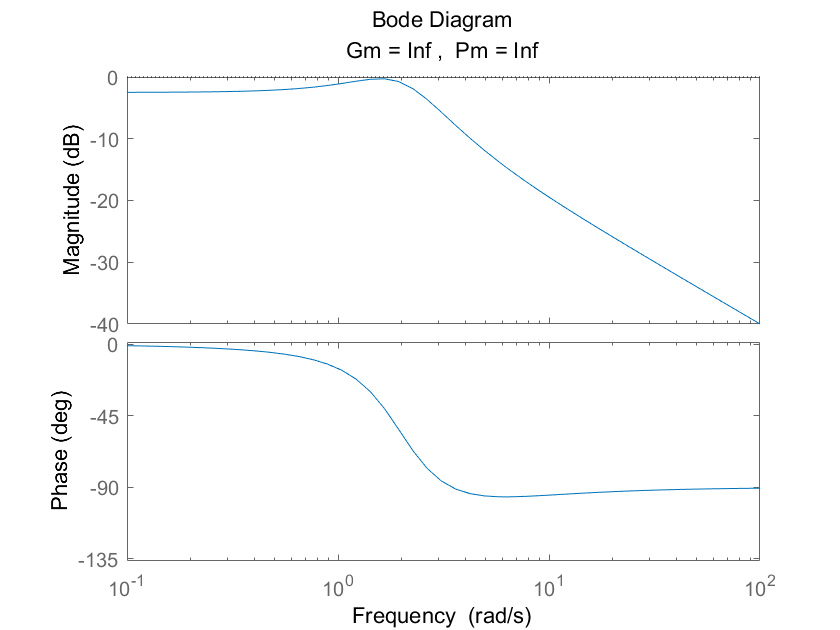


margin(num,den)

clear
clc

Wn = 6

Wn = 6

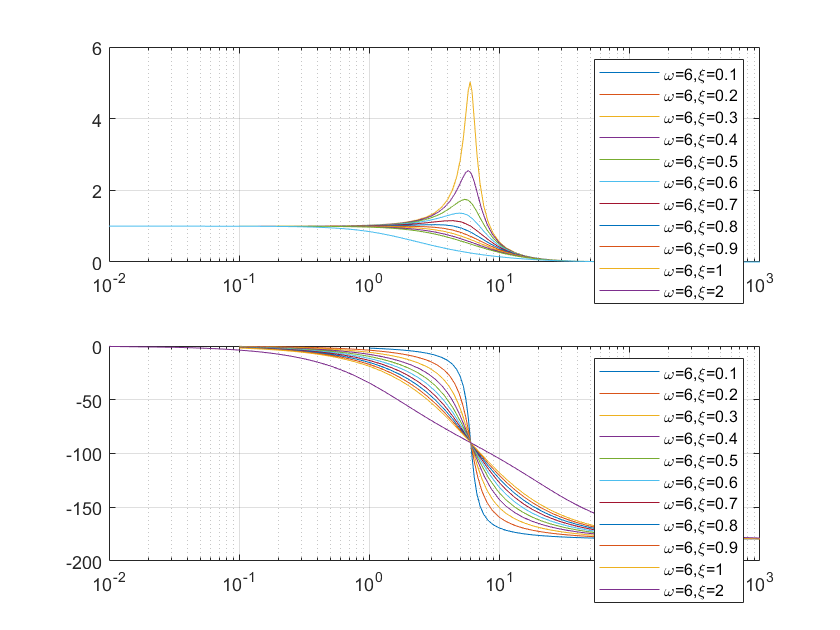

kesai = [0.1:0.1:1,2];
le = [];
x = '\omega=6,\xi=';

for kos=kesai
    num = Wn^2;
    den = [1,2*kos*Wn,Wn^2];
    
    [mag,pha,w1]=bode(num,den);
    subplot(2,1,1);
    hold on
    semilogx(w1,mag)
    
    grid on
    subplot(2,1,2);
    semilogx(w1,pha)
    hold on
    
    num2str(kos);
    y = [x,num2str(kos)];
    le = [le,string(y)];
    
end
subplot(2,1,1);
legend(le)

subplot(2,1,2);
legend(le)
grid on
hold off

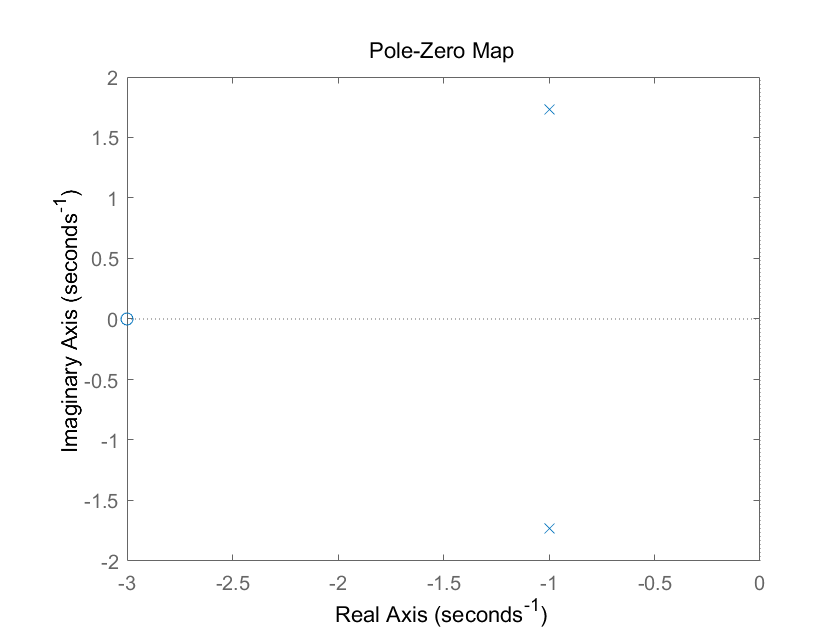

clear
clc
clf

num = [1,3];
den = [1,2,4];

pzmap(num,den)

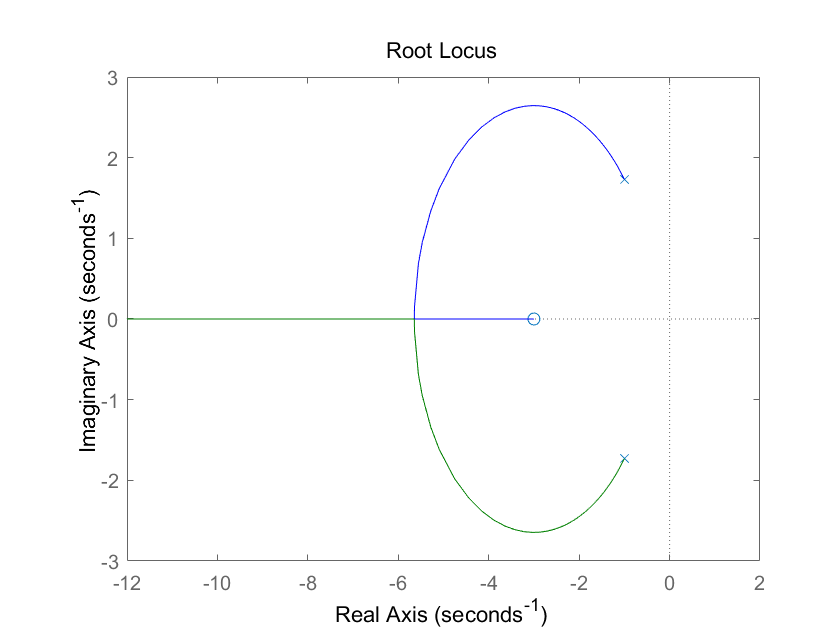


rlocus(num,den)

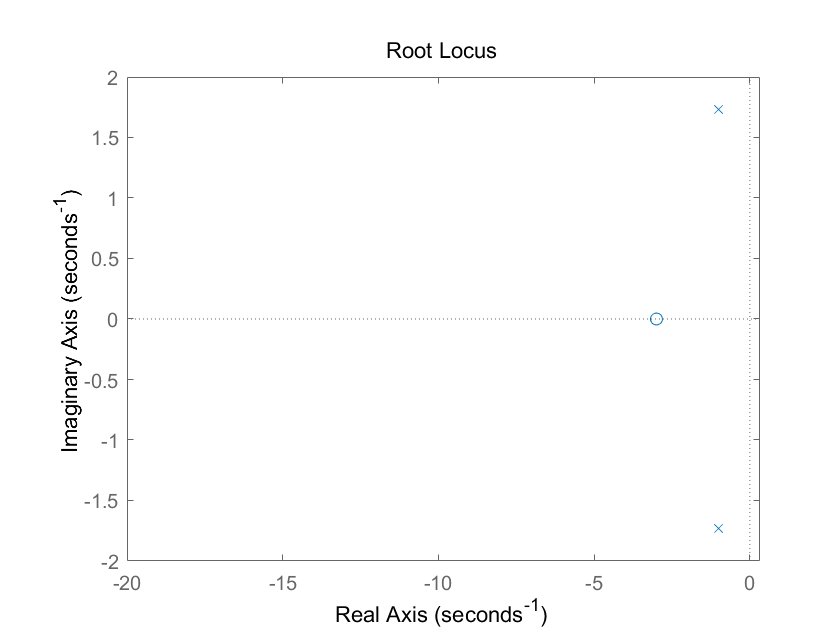


rlocus(num,den,18)


[k,plous]=rlocfind(num,den,12)

k = 11.4667

plous =    -9.3673
   -4.0994


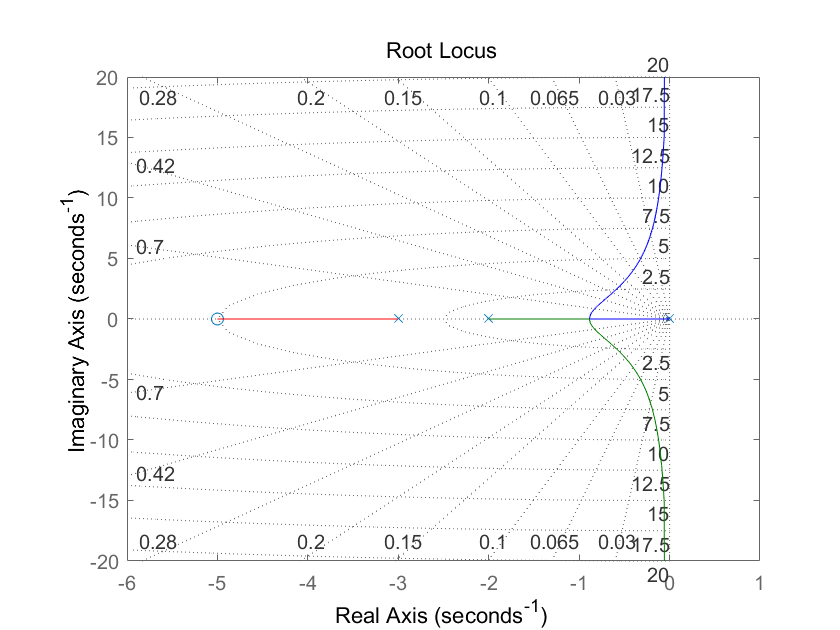

clear
clc
clf

num = [1 5];
den = [1 5 6 0];
rlocus(num,den)
sgrid

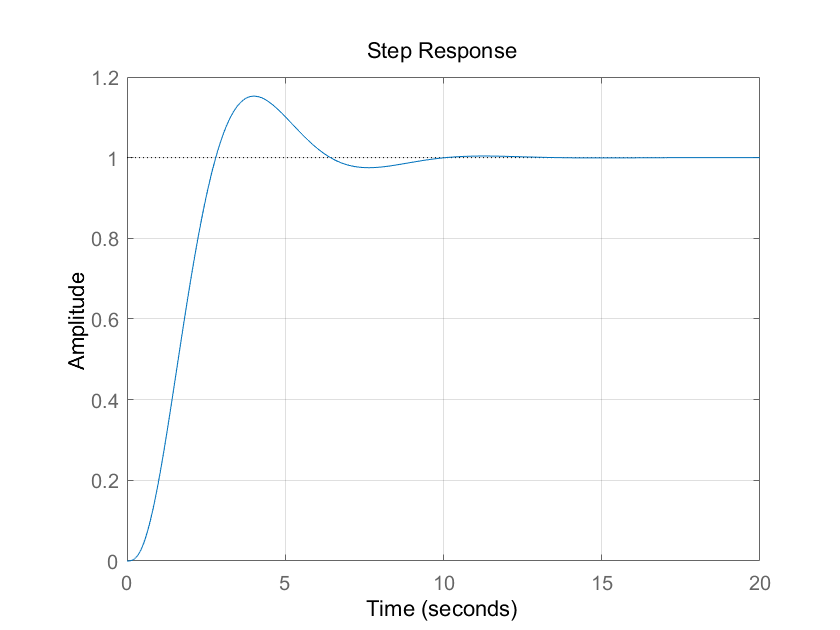


sys1 = tf([2],[1 0]);
sys2 = tf([2],[1 4]);
sys3 = tf([1],[1 0]);
sys4 = series(sys1,sys2);
sys5 = feedback(sys4,[1],[-1]);
sys6 = series(0.75*sys5,sys3);
sys = feedback(sys6,[1],[-1]);
t = 0:0.01:20;
[c,t] = step(sys,t);
step(sys,t)
grid on

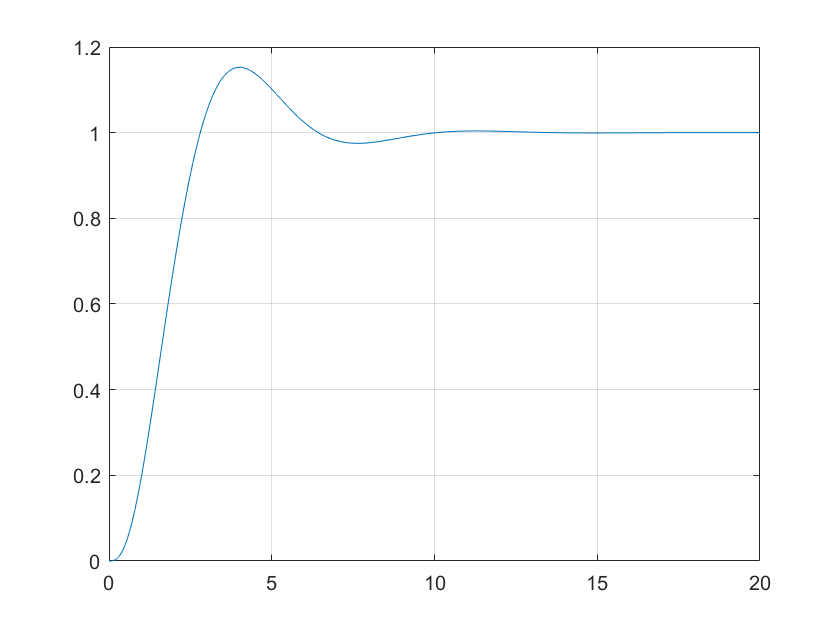

plot(t,c)
grid on

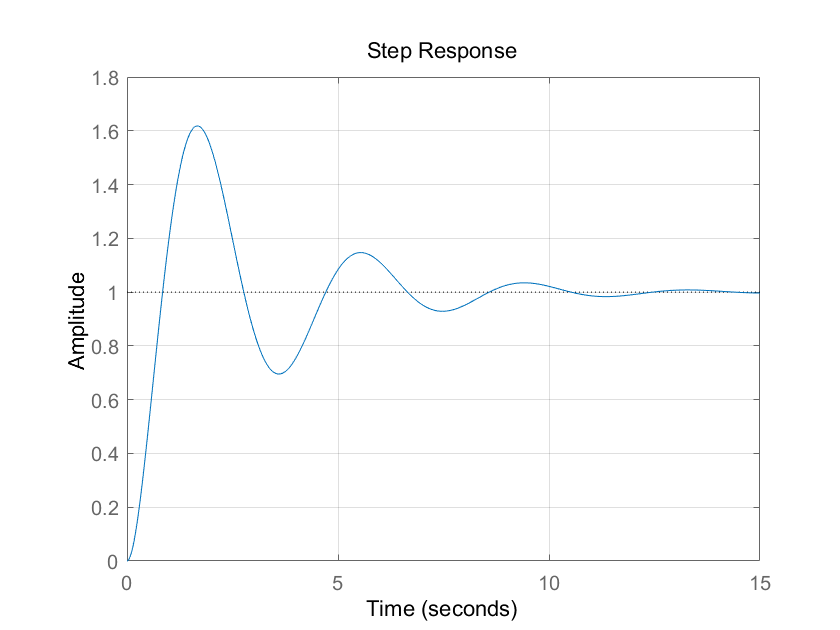

clear
clc
clf

t = [0:0.02:20];
num = [6.3223 18 12.811];
den = [1 6 11.3223 18 12.811];
step(num,den)
grid on

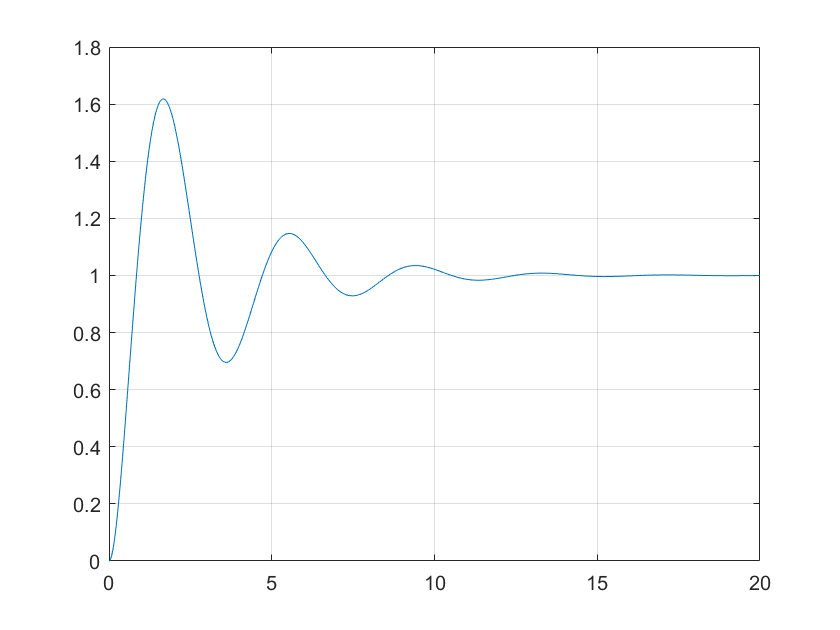

[y,x,t] = step(num,den,t);
plot(t,y)
grid on


r1 = 1;
while y(r1)<0.1
    r1 = r1+1;
end

r2 = 1;
while y(r2)<0.9
    r2 = r2+1;
end
rise_time = (r2-r1)*0.02

rise_time = 0.5800


[ymax,tp] = max(y);
peak_time = (tp-1)*0.02

peak_time = 1.6600


max_overshoot = ymax-1

max_overshoot = 0.6182


s = 1001;
while (y(s)>0.98) & (y(s)<1.02)
    s = s-1;
end
settling_time = (s-1)*0.02

settling_time = 10.0200

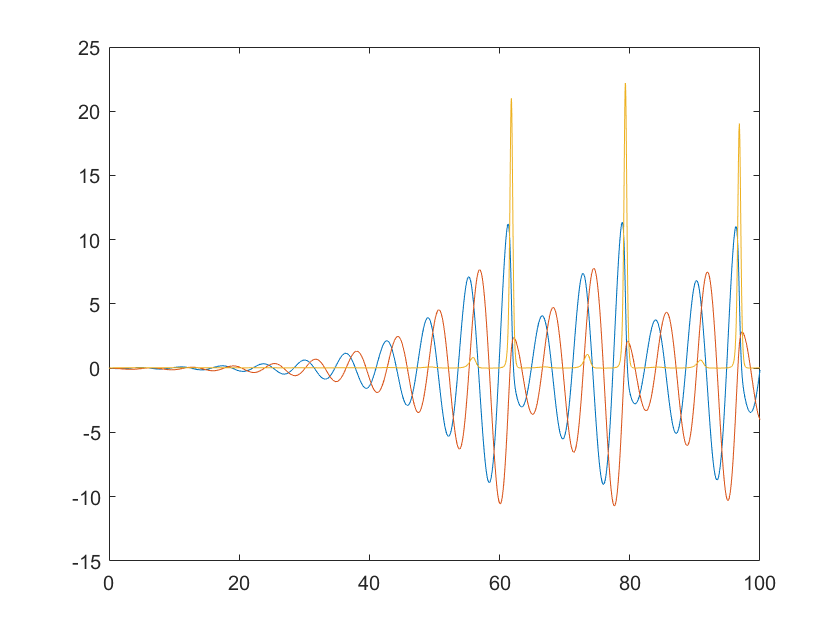

clear
clc
clf

x0 = [0;0;0];
[t,y]=ode45('ressler',[0,100],x0);
plot(t,y)

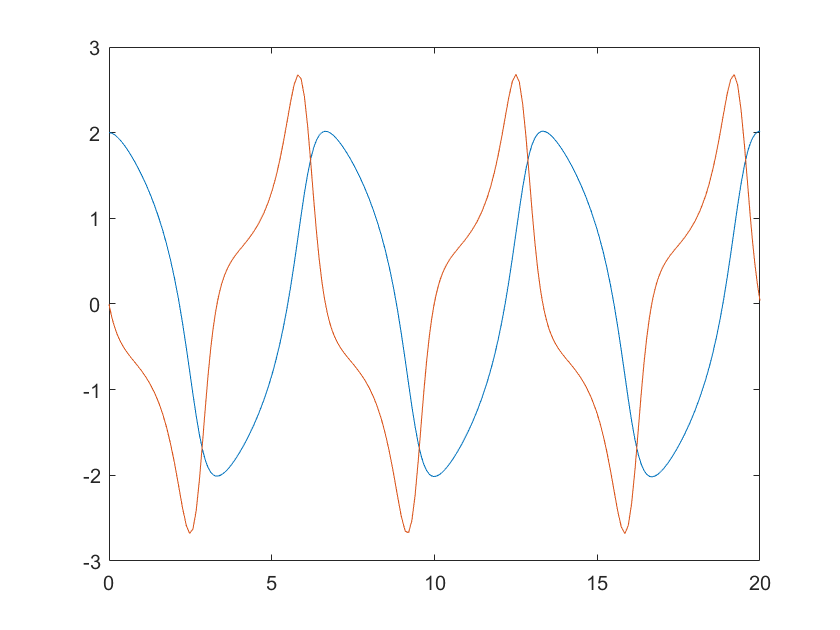

clear
clc
clf

ts = [0,20];
x0 = [2;0];
[t,y] = ode45(@fff,ts,x0);
plot(t,y)

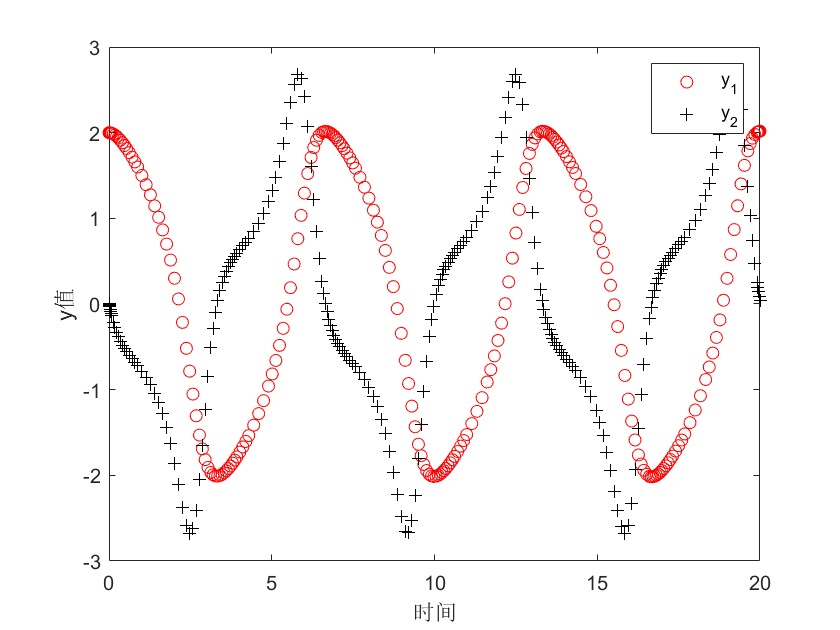

plot(t,y(:,1),'ro',t,y(:,2),'k+')
legend('y_{1}','y_{2}')
xlabel('时间')
ylabel('y值')

clear
clc
clf

A = [];
B = [];
Aeq = [];
Beq = [];
x_m = [-10 ;-10];
x_M = [10;10];
x0 = [5;5];

[x,fopt,key,c] = fmincon(@myobj,x0,A,A,Aeq,Beq,x_m,x_M,@mycon)


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =    -9.5474
    1.0474


fopt = 0.0236

key = 1

c = 包含以下字段的 struct :
         iterations: 20
          funcCount: 66
    constrviolation: 0
           stepsize: 0.0044
          algorithm: 'interior-point'
      firstorderopt: 8.2734e-07
       cgiterations: 0
            message: '↵Local minimum found that satisfies the constraints.↵↵Optimization completed because the objective function is non-decreasing in ↵feasible directions, to within the value of the optimality tolerance,↵and constraints are satisfied to within the value of the constraint tolerance.↵↵<stopping criteria details>↵↵Optimization completed: The relative first-order optimality measure, 8.273368e-07,↵is less than options.OptimalityTolerance = 1.000000e-06, and the relative maximum constraint↵violation, 0.000000e+00, is less than options.ConstraintTolerance = 1.000000e-06.↵↵'
       bestfeasible: [1×1 struct]


clear
clc
clf
